Условия задачи

F = @(x,y) -50*(y - cos(x));          %Простой пример жесткой задачи
x_0 = 0;
y_0 = 0;

RightBorder = 1;
h = 2/50;

Вызов методов

[Accurate_x, Accurate_y] = DormanPrince(F, x_0, y_0, h/4, RightBorder, 10^-10);
[Eu_x,Eu_y] = ExplicitRungeKuttaMethod(F, 4, x_0,y_0,h,RightBorder);
%[Eu_x,Eu_y] = RKC1(F, 5 ,0.05,x_0,y_0, 25/50 ,RightBorder);
%[Ee_x,Ee_y] = RKC1(F,2,0.2,x_0,y_0,h,RightBorder);
[Ee_x,Ee_y] =ExplicitRungeKuttaMethod(F, 1, x_0,y_0,h,RightBorder);
[C_x, C_y] = RKC1(F,2,0,x_0,y_0,h,RightBorder);

Построение графиков

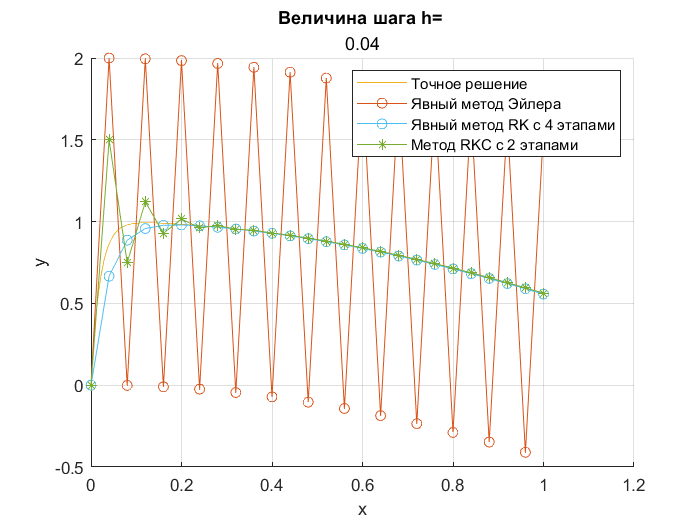

figure
hold on
grid on
xlabel('x')
ylabel('y')
plot (Accurate_x, Accurate_y, 'Color', '#EDB120');
plot (Ee_x, Ee_y, '-o');
plot (Eu_x, Eu_y, "Color", '#4DBEEE', 'Marker', 'o');
plot (C_x, C_y, 'Color', '#77AC30', 'Marker', '*');
title ("Величина шага h= ", h);
legend('Точное решение','Явный метод Эйлера','Явный метод RK с 4 этапами','Метод RKC c 2 этапами' )

%legend('Точное решение','RKC с 5 этапами и демпф.= 0.05 с шагом h= 1/2','Метод RKC с 2 этапами','Метод RKC c 2 этапами и демпф.=0.2' )
